clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;

xi = 0.690108;
wn = 1;
desiredPoles = [-xi*wn+wn*sqrt(1-xi^2)*1i; -xi*wn- wn*sqrt(1-xi^2)*1i]

desiredPoles =      -0.69011 +    0.72371i
     -0.69011 -    0.72371i


calcDamp(desiredPoles)

ans =       0.72371
     -0.72371


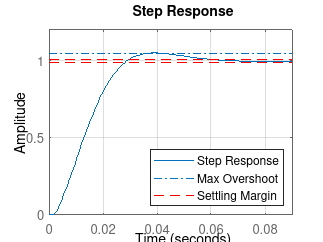


Cs = pidGen(0, 0, 80, 150,1);
% Cs = pidGen(1, .2, 1, 1,1);

figure(1); clf; hold on;
step(Cs*Ps/(1+Cs*Ps))
plot([0 1],[1.05 1.05],'-.')
plot([0 1],[1.01 1.01],'r--')
plot([0 1],[.99 .99],'r--')
legend('Step Response', 'Max Overshoot', 'Settling Margin',"Location",'southeast')
grid on;

poles1 = refPoles(0, 0, 80, 150)

poles1 =       -75.926 -       79.9i
      -75.926 +       79.9i
      -99.074 -     988.91i
      -99.074 +     988.91i


damps1 = calcDamp(poles1)

damps1 =      -0.72491
      0.72491
     -0.99502
      0.99502


wn = abs(poles1)

wn =        110.22
       110.22
       993.86
       993.86


info = stepinfo(Cs*Ps/(1+Cs*Ps))

info = struct with fields:
         RiseTime: 0.01877
    TransientTime: 0.054342
     SettlingTime: 0.054342
      SettlingMin: 0.90471
      SettlingMax: 1.0513
        Overshoot: 5.1324
       Undershoot: 0
             Peak: 1.0513
         PeakTime: 0.038818


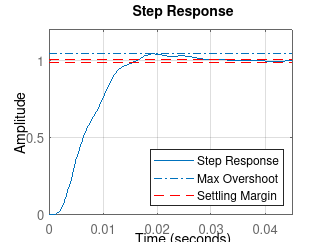




Cs = pidGen(0, 0, 150, 300,1);
figure(1); clf; hold on;
step(Cs*Ps/(1+Cs*Ps))
plot([0 1],[1.05 1.05],'-.')
plot([0 1],[1.01 1.01],'r--')
plot([0 1],[.99 .99],'r--')
legend('Step Response', 'Max Overshoot', 'Settling Margin',"Location",'southeast')
grid on;

poles2 = refPoles(0, 0, 80, 200)

poles2 =       -101.65 -     77.014i
      -101.65 +     77.014i
      -98.347 -     986.95i
      -98.347 +     986.95i


damps2 = calcDamp(poles2)

damps2 =      -0.60388
      0.60388
     -0.99507
      0.99507


wn = abs(poles2)

wn =        127.53
       127.53
       991.84
       991.84


info = stepinfo(Cs*Ps/(1+Cs*Ps))

info = struct with fields:
         RiseTime: 0.0089901
    TransientTime: 0.027176
     SettlingTime: 0.027176
      SettlingMin: 0.90226
      SettlingMax: 1.0453
        Overshoot: 4.5336
       Undershoot: 0
             Peak: 1.0453
         PeakTime: 0.019325


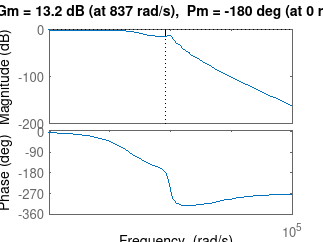



figure()
margin(Cs*Ps/(1+Cs*Ps))